# EE4620 Assignment 1

Question 1)

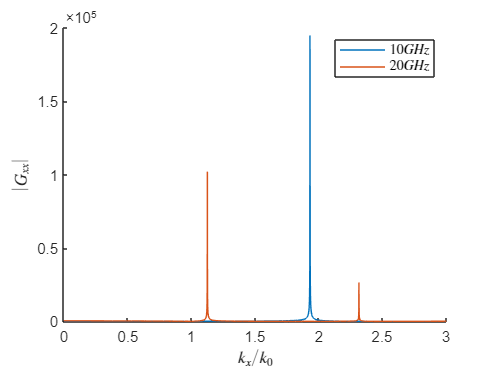

clear all
h = 4.5e-3;
z = h+eps ;
er = 6 ;
freq = [10,20].*1e9 ;
lambda = 3e8./freq ;
k_0 = 2*pi./lambda ;
ky = 0 ;
zeta0 = 120*pi ;

kx_1 = linspace(eps,3.*k_0(1),3001) ;
krho = sqrt(kx_1.^2 + ky.^2) ;
[vtm, vte, itm, ite, ks] = txline_GroundSlab(k_0(1),zeta0,er,z,h,krho,freq(1)) ; 
ej_sgf = SpectralGFej(k_0(1),ks,er,kx_1,ky,vtm,vte,itm,ite,zeta0,krho,z,h) ;
Gxx = ej_sgf(:,:,1,1) ;


kx_2 = linspace(eps,3.*k_0(2),3001) ;
krho = sqrt(kx_2.^2 + ky.^2) ;
[vtm, vte, itm, ite, ks] = txline_GroundSlab(k_0(2),zeta0,er,z,h,krho,freq(2)) ; 
ej_sgf = SpectralGFej(k_0(2),ks,er,kx_2,ky,vtm,vte,itm,ite,zeta0,krho,z,h) ;
Gxxnew = ej_sgf(:,:,1,1) ;

figure
hold on
plot(kx_1/k_0(1),abs(Gxx),'DisplayName','$10GHz$') ;
plot(kx_2/k_0(2),abs(Gxxnew),'DisplayName', '$20GHz$')  ;
hold off
legend('Interpreter','latex')
xlabel('$k_x/k_0$',Interpreter='latex')
ylabel('$|G_{xx}|$',Interpreter='latex')


% plot(20*log10(abs(Gxx))-20*log10(max(abs(Gxx))))
 

Question 2) 

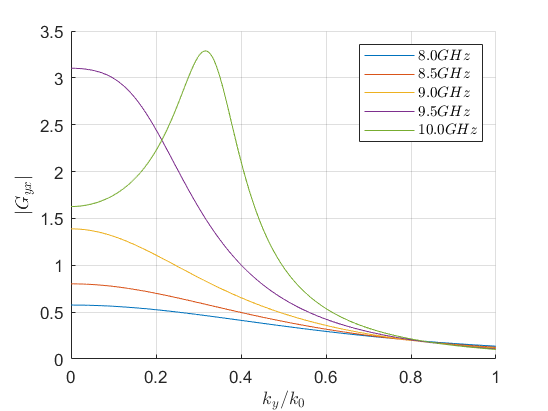

clear all
h = 15.6e-3;
hs = 2.6e-3 ;
z = h+hs+eps ;
er = 10 ;
freq = (8:0.5:10).*1e9 ;
lambda = 3e8./freq ;
k_0 = 2*pi./lambda ;
kx = 0 ;
zeta0 = 120*pi ;

figure
hold on
for ii=1:length(freq)

    ky_1 = linspace(eps,k_0(ii),3001) ;
    krho = sqrt(kx.^2 + ky_1.^2) ;

    [vtm, vte, itm, ite, ks] = trxline_Superstrate(k_0(ii),zeta0,er,h,hs,krho,'Layer3',z,freq(ii)) ;
    em_sgf = SpectralGFem(k_0(ii),ks,er,kx,ky_1,vtm,vte,itm,'Layer2',zeta0,krho) ;
    Gyx(ii,:) = em_sgf(:,:,2,1) ; % y component of e field for x oriented magnetic current source
    
    plot(ky_1/k_0(ii),abs(Gyx(ii,:)),'DisplayName',sprintf('$ %.1f GHz $',freq(ii)/1e9)) ;

end
legend('-DynamicLegend');
legend('show') ;
legend('Interpreter','latex');
xlabel('$ k_y/k_0 $',Interpreter='latex')
ylabel('$|G_{yx}|$',Interpreter='latex')
grid on
hold off

Question 3)

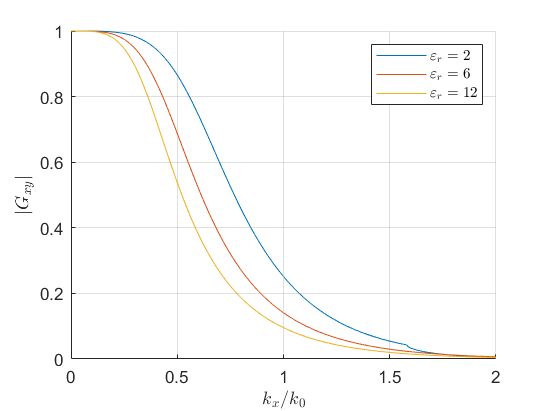

clear all
clc
h = 5e-3 ;
freq = 30e9 ;
z = h+eps ;
er = [2.5,6,12];
lambda = 3e8/freq ;
k_0 = 2*pi./lambda ;
ky = 0 ;
zeta0 = 120*pi ;
kx = linspace(eps,2.*k_0,3001) ;

figure
hold on
for ii=1:length(er)
    krho = sqrt(kx.^2 + ky.^2) ;

    [vtm, vte, itm, ite, ks] = trxline_semi_inf_Superstrate(k_0,zeta0,er(ii),h,krho,z,freq,'Layer2') ;
    em_sgf = SpectralGFem(k_0,ks,er(ii),kx,ky,vtm,vte,itm,'Layer1',zeta0,krho) ;
    Gxy(ii,:) = em_sgf(:,:,1,2) ; % x component of e field for y oriented magnetic current source
    
    plot(kx/k_0,abs(Gxy(ii,:)) , 'DisplayName',sprintf( '$ \\varepsilon_r  = %.0f $',er(ii))) ;

end
legend('-DynamicLegend');
legend('show') ;
legend('Interpreter','latex');
xlabel('$k_x/k_0$',Interpreter='latex')
ylabel('$|G_{xy}|$',Interpreter='latex')
grid on;
hold off